# HW3: Differential Drive Path Following using Forward Kinematics

In this example, a differential drive robot navigates a set of waypoints using the Pure Pursuit algorithm while avoiding obstacles using the Vector Field Histogram algorithm.

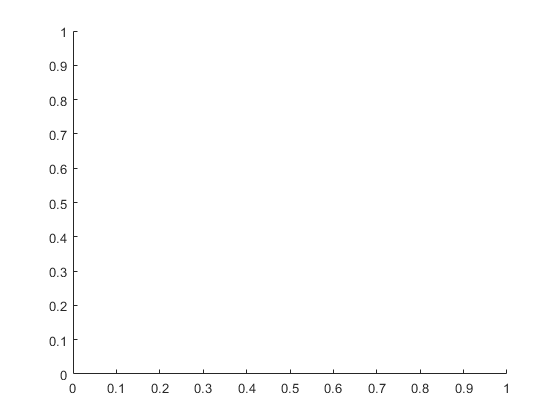

Error using internal.createMapFromName (line 25)
Invalid map name 'map' in base and model workspaces.

Error in Visualizer2D/setupImpl (

% Set occupancy of world locations and show map. 
close all
clear
map1 = imread(['test1.pbm']);
map = robotics.BinaryOccupancyGrid(map1, 200);
show(map)

## Simulation setup

Define Vehicle

% create robot
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Angular velocity of a robot wheels
wL = 1;
wR = -0.5;
[v,w] = forwardKinematics(dd,wL,wR)

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:40;        % Time array

% Initial conditions
initPose = [2;2;0];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;

## Create and Modify Binary Occupancy Grid

gjg

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi/2,pi/2,50); %50 number of points
lidar.maxRange = 5;

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.robotRadius = 0.2;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

## Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             16 9];

% Pure Pursuit Controller
controller = robotics.PurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;
controller.DesiredLinearVelocity = 0.75;
controller.MaxAngularVelocity = 1.5;

% Vector Field Histogram for obstacle avoidance
vfh = robotics.VectorFieldHistogram;
vfh.DistanceLimits = [0.05 3];
vfh.NumAngularSectors = 36;
vfh.HistogramThresholds = [5 10];
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.25;

## Simulation loop

r = robotics.Rate(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end